## Info

This live script describes the design procedure in which robust stability is obtained for the system, aswell as stability for the decoupled system. Finally the Performance of the system Z/W is also considered with a weight on the output Z. This allows for weighting how the performance should be calculated the weigth is called wz and takes a Transfer function and converts it to statespace. This procedure only check the nominal perforamnce of the system and does not consider how the unertanitys may effect the performance. 

## Initilization

clc
clear

disp("Initilization Procedure")

Initilization Procedure


model.Parameters
param.ctrl.T_ref = util.Celsius2Kelvin(20);

T_kelvin = 293.1500

param = control.calculateOperatingPoint(param);

Calculate Operating Point for T_a = 293.150000 [K]

param = model.calculateModel(param);

Calculate bilinear model matrices
Calculate linearisation decoupled
Calculate linearisation coupled
Testing controlability
Testing T_ref


param = model.calculateWDelta(param,0);
simtime = 10*60;




## Control

% Initializes yalmip and optimisation variables.
    s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


    yalmip('clear')
    q = cell(1,param.n + 1);
    y = cell(1,param.n);
    for i=1:param.n
        q{i} = sdpvar(3);
        y{i} = sdpvar(1,3,'full');
    end
    q{end} = sdpvar(4);
    qwz = sdpvar(4)

Linear matrix variable 4x4 (symmetric, real, 10 variables)
Coefficient range: 1 to 1


    Q_small = blkdiag(q{1:end-1});
    Q = blkdiag(Q_small,q{end});
    Q_hat = blkdiag(Q_small,qwz);
    Y_small = blkdiag(y{:});
    Y = blkdiag(Y_small, sdpvar(4));
    Y_hat = blkdiag(Y_small,sdpvar(4));
    isGammaOne = 0

isGammaOne = 0

    info = 0

info = 0

    % Is gamma = 1 or an optimisation variable
    if isGammaOne
        gamma = 1;
    else
        gamma = sdpvar(1);
    end
    gammap = sdpvar(1);
    % % Structure the matrices
    % A_split = [param.model.A, zeros(12,4); zeros(4,12), param.model.Awd];
    % B_split = [param.model.B, zeros(12,4); param.model.Bwd, zeros(4,4)];
    % % K_split = [K, zeros(4); zeros(4), eye(4)]
    % B_mw = [param.model.B ; zeros(4)];
    % C_split = [param.model.Dwd, param.model.Cwd];
    % D_mw = zeros(4);


    % Structure the matrices
    A_split = [param.model.A, zeros(12,4); zeros(4,12), param.model.Awd];
    B_split = [param.model.B, param.model.B * param.model.Cwd; zeros(4,4), zeros(4,4)];
    % K_split = [K, zeros(4); zeros(4), eye(4)]
    B_mw = [param.model.B * param.model.Dwd; param.model.Bwd];
    C_split = [eye(4), zeros(4)];
    D_mw = zeros(4);

    Bw = -blkdiag([0;0;1],[0;0;1],[0;0;1],[0;0;1]);
    wz= eye(4)*(s-10)/(s-100)*db2mag(-200)

wz =
 
  From input 1 to output...
       1e-10 s - 1e-09
   1:  ---------------
           s - 100
 
   2:  0
 
   3:  0
 
   4:  0
 
  From input 2 to output...
   1:  0
 
       1e-10 s - 1e-09
   2:  ---------------
           s - 100
 
   3:  0
 
   4:  0
 
  From input 3 to output...
   1:  0
 
   2:  0
 
       1e-10 s - 1e-09
   3:  ---------------
           s - 100
 
   4:  0
 
  From input 4 to output...
   1:  0
 
   2:  0
 
   3:  0
 
       1e-10 s - 1e-09
   4:  ---------------
           s - 100
 
Continuous-time transfer function.


    wzSS = ss(wz);
    Cz = blkdiag([0 0 1],[0 0 1],[0 0 1],[0 0 1]);
    A_hat = [param.model.A, zeros(12,4);
             wzSS.B*Cz wzSS.A]; 
    B_hat =[param.model.B, zeros(12,4);
            zeros(4,8)]; 
    Bmp = [Bw;
           zeros(4)];
    Cmp = [wzSS.D*Cz,wzSS.C]; 
    
    Dmp = zeros(4);
    
    

    % Setup constraint
    
    %Lyap stabilising the decoupled system
    constraints = param.model.A * Q_small + Q_small * param.model.A.' + param.model.B_Bar * Y_small + Y_small.' * param.model.B_Bar.' <=0;
    %Performance 
    constraints = [constraints,
                   [Q_hat*A_hat.'+Y_hat.'*B_hat.' + A_hat*Q_hat+B_hat*Y_hat, Bmp, Q_hat*Cmp.';
                    Bmp.', -gammap*eye(4), Dmp.';
                    Cmp*Q_hat,Dmp, -gammap*eye(4)] <= 0]; 
    %Robust stability 
    constraints = [constraints, [A_split * Q + Q * A_split.' + B_split * Y + Y.' * B_split.', B_mw, Y.' * C_split.';
                    B_mw.', -gamma * eye(4), D_mw;
                    C_split * Y, D_mw.', -gamma * eye(4)] <= 0];
    constraints = [constraints,  Q >= 0, gamma >= 0, gamma <= 1,gammap >=0];
    options = sdpsettings('verbose',0,'solver','mosek');
    if info
        sol = optimize(constraints, [gammap], options)
        check(constraints)
    else
        sol = optimize(constraints, gamma, options);
    end
    
    % Recovers the controller from the variables
    K = value(Y_small)/value(Q_small);
    Ks = zeros(1,3,param.n);
    for i=1:param.n
        Ks(:,:,i) = K(i,3*(i-1)+1:3*i);
    end

    % Evaluation of the results from the design procedure
    fprintf("Evaluation of design procedure 2 \n")

Evaluation of design procedure 2 


    if(eig(value(Q))<=0)
        fprintf("Q is not positive definite!!!\n")
    else
        fprintf("Q is positive definite\n")
    end

Q is positive definite


    eig(value(Q)).'

ans =     0.0017    0.0018    0.0020    0.0225    0.2117    0.2135    0.2136    0.2258    1.4072    1.4072    1.4072    1.4072    4.7709    9.2700    9.3236    9.4497



    fprintf("Gamma is found to be:\n")

Gamma is found to be:


    value(gamma)

ans = 0.2282


    if(eig(param.model.A+param.model.B_Bar*K) > 0)
        fprintf("One or more eigenvalues in the decoupled system is positive!!! \n")
    else
        fprintf("Eigenvalues of the decoupled systems are all negative \n")
    end

Eigenvalues of the decoupled systems are all negative 


    eig(param.model.A+param.model.B_Bar*K).'

ans =    -4.0552   -0.5867   -0.0896   -8.9372   -4.0164   -0.0272   -7.1466   -3.9633   -0.0266   -7.8244   -3.9723   -0.0269



    if(eig(param.model.A+param.model.B*K) > 0)
        fprintf("One or more eigenvalues in the coupled system is positive!!! \n")
    else
        fprintf("Eigenvalues of the coupled systems are all negative \n")
    end

Eigenvalues of the coupled systems are all negative 


    eig(param.model.A+param.model.B*K).'

ans =   -20.3110  -17.8959  -14.1021   -1.2877   -4.1369   -4.0249   -3.9803   -3.9842   -0.0849   -0.0266   -0.0272   -0.0269


    %saves the block version of K this is used further in some simulations
    param.ctrl.K = K;
    %saves a 3d matrix version of Ks this is used in the simulation of the
    %nonlinear system.
    param.ctrl.Ks = Ks;
    disp("gammap was found to be")

gammap was found to be


    value(gammap)

ans = 2.8037

    Mw = model.calculateMw(param);

s =
 
  s
 
Continuous-time transfer function.
Model Properties


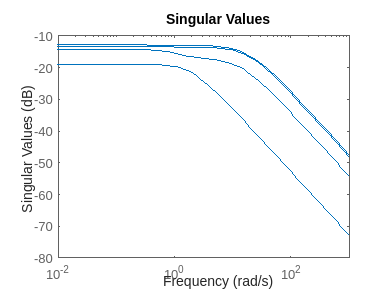

    figure()
    sigma(Mw)

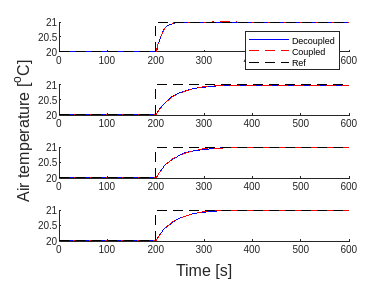

ans = 1×4 struct array with fields:
    time
    Tw
    Ta
    T


    
     util.SimulateStep(param,"TestPerformance",0)

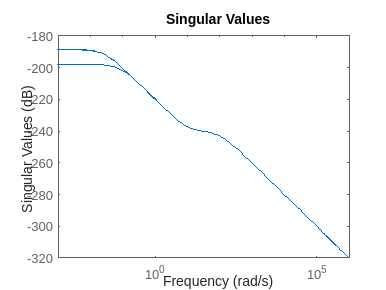



    MP = Cmp/(s*eye(16)-(A_hat+B_hat*blkdiag(K,eye(4))))*Bmp+Dmp;
    figure()
    sigma(MP)